## Import Data and Best Model

% load data
clear
clear all
close all
clc
format shorteng
[dsTrain, dsValidation, dsTest, dsCombined] = import_all("pressure_train.csv", "pressure_val.csv", "pressure_test.csv", "pressure_combined.csv");

% load best model
load('pressure_DL.mat')

% set colours
blue = [0.00 0.00 0.55];
red = [0.65 0.16 0.16];
green = [0.00 0.39 0.00];
pink = [1.00,0.00,1.00];

## Training History

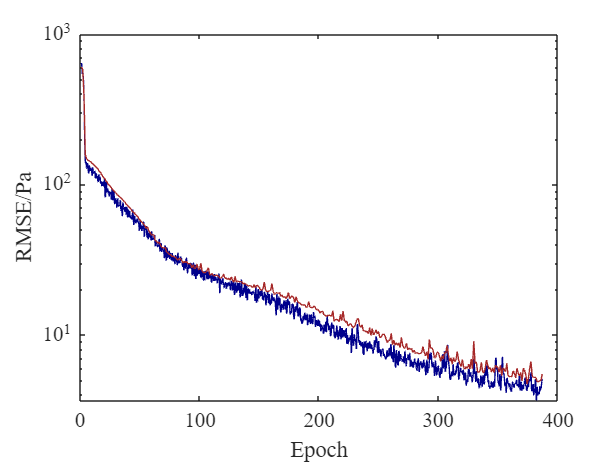

training_RMSE = smoothdata(pressure_DL_traininfo.TrainingRMSE, "gaussian", 50);
validation_RMSE = pressure_DL_traininfo.ValidationRMSE;
% change minibatch size as needed
MiniBatchSize = 62;
iter = length(training_RMSE);
iter_per_epoch = floor(length(readall(dsTrain)) / MiniBatchSize);
num_epoch = ceil(iter / iter_per_epoch);
epochs = linspace(1,num_epoch,length(training_RMSE));
x = linspace(1,num_epoch,length(training_RMSE));
y = validation_RMSE;
idx = ~any(isnan(y),1);

figure(1)
hold on
plot(epochs, training_RMSE, 'Color', blue)
plot(x(idx),y(idx), 'Color', red)
hold off

v=get(1,'currentaxes');
xlabel("Epoch")
ylabel("RMSE/Pa", 'FontSize',20)
% legend("Train (smoothed)", "Validation")
set(v,'FontSize',14,'FontName','Times New Roman', 'YScale','log')
box on

clear iter iter_per_epoch MiniBatchSize idx x y

## Results (Test)

y_test_pred = predict(pressure_DL_net,dsTest);
data = readall(dsTest);
y_test = cell2mat(data(:,2));
test_RMSE = rmse(y_test,y_test_pred)

test_RMSE = single
     4.8717e+000


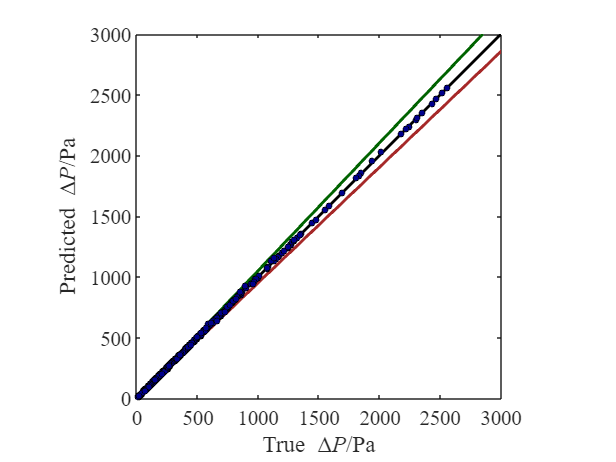

plot_true_pred(2, y_test, y_test_pred, 0, [0 3000 0 3000])

## Results (All)

y_comb_pred = predict(pressure_DL_net,dsCombined);
data = readall(dsCombined);
y_comb = cell2mat(data(:,2));
comb_RMSE = rmse(y_comb,y_comb_pred)

comb_RMSE = single
     4.1910e+000


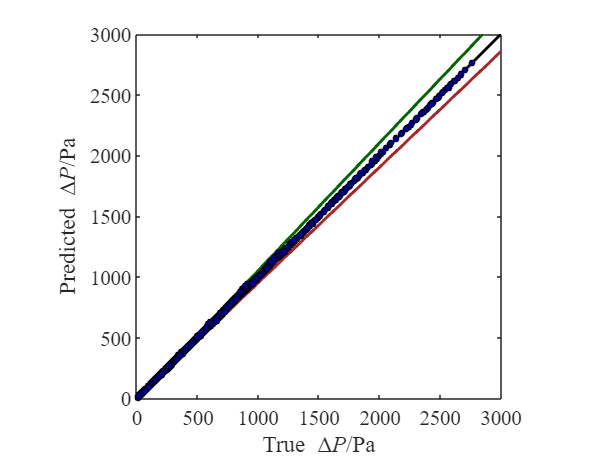

plot_true_pred(3, y_comb, y_comb_pred, 0, [0 3000 0 3000])

## Others

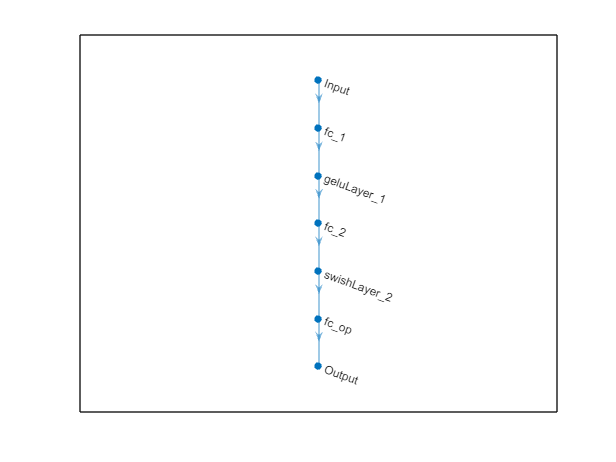

pressure_DL_net.plot

pressure_DL_net.Layers

ans =   7×1 Layer array with layers:

     1   'Input'          Feature Input       6 features with 'zscore' normalization
     2   'fc_1'           Fully Connected     48 fully connected layer
     3   'geluLayer_1'    GELU                GELU
     4   'fc_2'           Fully Connected     29 fully connected layer
     5   'swishLayer_2'   Swish               Swish
     6   'fc_op'          Fully Connected     1 fully connected layer
     7   'Output'         Regression Output   mean-squared-error with response 'Response'

pressure_DL_net.layerGraph

ans =   LayerGraph with properties:

     InputNames: {'Input'}
    OutputNames: {'Output'}
         Layers: [7×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]


function plot_true_pred(num, y_true, y_pred, lgnd, axs)
    % set colours
    blue = [0.00 0.00 0.55];
    red = [0.65 0.16 0.16];
    green = [0.00 0.39 0.00];

    figure(num)
    hold on
    % plot points
    s = plot(y_true,y_pred,'o','MarkerEdgeColor','k','MarkerFaceColor',blue,'MarkerSize',4);
    line = [0 axs(2)];
    plot(line, line, "LineWidth", 2, "Color", "k");
    plot(0.95*line, line, "LineWidth", 2, "Color", green);
    plot(1.05*line, line, "LineWidth", 2, "Color", red);
    uistack(s,'top')
    hold off
    
    v=get(num,'currentaxes');
    xlabel('True\rm \Delta{\itP}/Pa')
    ylabel('Predicted \Delta{\itP}/Pa')
    if lgnd == 1
        legend('Ideal','5% Above', '5% Below', '', "FontSize", 18, 'Location', 'nw');
    end
    set(v,'FontSize',14,'FontName','Times New Roman', 'XTick', get(v, 'YTick'), 'XTickLabelRotation', 0);
    axis(axs)
    box on
    axis square
end